# Relatório de Atividade 09 - Variáveis de experimentação 

*Débora Nunes Pinto de Oliveira*

*Prof. Antonio Marcus, Estimação e Identificação de Sistemas 21.2*

*04 de Outubro de 2021*

Esse documento tem por objetivo descrever as variáveis de escolha que devem ser adotadas pelo usuário ao identificar uma planta desconhecida. Inicialmente, serão tratadas as decisões para a aquisição dos dados. Em seguida, será descrito como avaliar os dados coletados antes de empregar algoritmos de estimação (como método dos mínimos quadrados).

## Introdução

O objetivo da identificação de um processo desconhecido é encontrar um modelo confiável para representar a planta. Para esse processo, o usuário deve tomar uma série de decisões para garantir a aquisição de um "bom" modelo, por exemplo: como os dados devem ser coletados, qual modelo deve ser utilizado, qual algoritmo de estimação deve ser empregado, e como validar o modelo estimado. Todas essas variáveis de escolha são denominadas como o conjunto $\mathcal{D}$, tais como número $N$ de amostras, sinais amostrados e ordem do modelo. 

Primeiramente, é necessário formalizar o que é considerado um "bom" modelo, uma vez que esse conceito é subjetivo. Nesse estudo, a qualidade do modelo estimado será dependente a como o sistema será utilizado. Além disso, é importante destacar que a adoção de algumas suposições sobre o sistema modelado é inevitável. Por exemplo, iremos considerar que a planta obedece um modelo:


$$y(t)=G_0(q)u(t)+H_0(q)e_o(t)$$


para $e_0(t)$ um ruído branco de média nula e variância $\lambda_0$. Obviamente, a consideração de certas propriedades na geração dos dados é questionável. Todavia, as propriedades desses modelos quando feitas essas considerações facilitam os cálculos, mesmo quando  tais alegações não são verificáveis [1].

Para simplificar a notação, usaremos:


$$T_0(q)=[G_0(q)\;\;H_0(q)]$$


Analogamente, os polinômios do modelo estimado são dados por:

 
$$\hat{T}(q,\mathcal{D})=[\hat{G}(q,\mathcal{D})\;\;\hat{H}(q,\mathcal{D})]$$


É desejável que o erro $\tilde{T}(e^{j\omega},\mathcal{D})$ entre o modelo estimado $\hat{T}(q,\mathcal{D})$ e $T_0(q)$ seja mínimo:


$$\tilde{T}(e^{j\omega},\mathcal{D}) \stackrel{\Delta}{=} \hat{T}(e^{j\omega},\mathcal{D})-T_0(e^{j\omega})$$


no qual $\Delta$ se refere às restrições definidas pelo usuário, tais como número máximo de amostras, potência máxima do sinal e complexidade de procedimentos numéricos. Dependendo do uso do sistema estimado, a minimização do erro em algumas frequências pode ser mais importante do que em outras. Dessa forma, será introduzido um critério escalar ponderado na frequência:

$J_1(\tilde{T}(\cdot,\mathcal{D}))=\int_{-\pi}^{\pi}\tilde{T}(e^{j\omega},\mathcal{D})C(\omega)\tilde{T}^T(e^{-j\omega},\mathcal{D})d\omega$, para $C(\omega)=\left[\matrix{ C_{11}(\omega) &  C_{12}(\omega) \cr C_{21}(\omega) &C_{22}(\omega)}\right]$

A matriz $C(\omega)$ descreve a importância de diferentes frequências (colunas) e dos polinômios $G$ e $H$ (linhas) no ajuste de $\hat{T}(q,\mathcal{D})$em relação a $T_0(q)$. Nos exemplos a seguir, será explicado como encontrar essa matriz de ponderação. 

Como $\hat{T}(q,\mathcal{D})$ é uma variável aleatória, $J_1$ também será uma variável aleatória. Logo, para encontrar uma realização dessa variável independente da medição, podemos tratar $\bar{J}(\mathcal{D})$ como a expectativa matemática de $J_1$:


$$\bar{J}(\mathcal{D})=\int_{-\pi}^{\pi}E[\tilde{T}(e^{j\omega},\mathcal{D})C(\omega)E\tilde{T}^T(e^{-j\omega},\mathcal{D})]d\omega = \int_{-\pi}^{\pi}\text{tr}[\Pi (\omega,\mathcal{D})C(\omega)]d\omega$$


para $\Pi(\omega,\mathcal{D})=\tilde{T}^T(e^{-j\omega},\mathcal{D})\tilde{T}(e^{j\omega},\mathcal{D})$, ou seja, o erro médio quadrático. Tendo em vista a consideração supracitada, o problema de identificação pode ser então resumido a encontrar as variáveis de projeto $\mathcal{D}$ tal que:


$$\min_{\mathcal{D}\in\Delta}\bar{J}(\mathcal{D})$$


### Exemplo 1: Simulação

Para esse exemplo, considera-se um modelo sem erro de saída, isto é:


$$y_\mathcal{D} = \hat{G}(q,\mathcal{D})u(t)$$


e um sistema real:


$$y_0(t)=G_0(q)u(t)$$


O erro é então dado pelo sinal:


$$\tilde{y}_\mathcal{D}=y_\mathcal{D} -y_0(t)=[\hat{G}(q,\mathcal{D})-G_0(q)]u(t)$$


e o espectro desse erro é:


$$\Phi_{\tilde{y}}(\omega,\mathcal{D})=|\hat{G}(q,\mathcal{D})-G_0(q)|^2\Phi_{u}(\omega)$$


Como $\hat{G}(q,\mathcal{D})$ é uma variável aleatória, $\Phi_{\tilde{y}}(\omega,\mathcal{D})$ também será uma variável aleatória. Considerando $\Psi_{\tilde{y}}(\omega,\mathcal{D})=E[\Phi_{\tilde{y}}(\omega,\mathcal{D})]$, a média da degradação da performance (do erro) conforme os erros no modelo $\hat{G}(q,\mathcal{D})$ é dada por:


$$\Psi_{\tilde{y}}(\omega,\mathcal{D})=E[|\hat{G}(q,\mathcal{D})-G_0(q)|^2\Phi_{u}(\omega)]$$


Considerando $C(\omega)=\left[\matrix{\Phi_{u}(\omega) &  0\cr 0&0}\right]$, é possível reescrever $\Psi_{\tilde{y}}(\omega,\mathcal{D})$ como:


$$\Psi_{\tilde{y}}(\omega,\mathcal{D}) = \text{tr}[\Pi (\omega,\mathcal{D})C(\omega)]$$


A variância média do erro de saída $E[\tilde{y}^2(t)]$ em relação a $u(t)$ pode ser dada por:


$$2\pi E[\tilde{y}^2(t)]=\bar{J}(\mathcal{D})=\int_{-\pi}^{\pi}\Psi_{\tilde{y}}(\omega,\mathcal{D})d\omega$$


Esse é um caso especial de $\bar{J}(\mathcal{D})$, que ilustra a interpretação física para a escolha do modelo por critério quadrático.

### Exemplo 2: Preditor

Conforme as atividades anteriores, o preditor de um passo a frente é dado por:


$$\hat{y}(t|t-1)= H^{-1}(q)G(q)u(q)-[1-H^{-1}(q)]y(t)$$


O erro entre a predição $\hat{y}_\mathcal{D}(t|t-1)$ a partir do modelo $\hat{T}(q,\mathcal{D})$ e as predições reais $\hat{y}_0(t|t-1)$ pode ser escrita como:


$$\tilde{y}_\mathcal{D}(t|t-1) = [\hat H^{-1}(q)\hat G(q) - H^{-1}_0(q)G_0(q)]u(t)-[H^{-1}_0(q)-\hat {H}^{-1}(q)]y(t)$$


Substituindo $y(t)=G_0(q)u(t)+H_0(q)e_0(t)$, obtém-se que:


$$\tilde{y}_\mathcal{D}(t|t-1) =\hat H^{-1}[\tilde{G}(q)u(t)+\tilde{H}e_o]  = \hat H^{-1}(q,\mathcal{D})\tilde{T}(q,\mathcal{D})
\left[\matrix{u(t)\cr e_0(t)}\right]$$


cujo espectro é dado por;


$$\Phi_{\tilde{y}}(\omega,\mathcal{D})=\frac{1}{|\hat{H}(e^{j\omega})|^2}\tilde{T}(e^{j\omega},\mathcal{D})
\left[\matrix{
\Phi_u(\omega)&\Phi_{ue}(\omega)\cr
\Phi_{ue}(\omega)&\lambda_0}\right]

\tilde{T}^T(e^{-j\omega},\mathcal{D})
$$


Assumindo que o erro $\tilde{T$ é tão pequeno que os termos de ordem mais alta podem ser negligenciados, nós podemos substituir $\hat{H}$ por $H_0$. Dessa forma, o espectro aproximado da média do sinal de erro $\tilde{y}$ é:

$\Psi_{\tilde{y}}(\omega,\mathcal{D}) = \text{tr}[\Pi (\omega,\mathcal{D})C(\omega)]$, para $C(\omega)=\frac{1}{|H_0(e^{j\omega})|^2}\left[\matrix{
\Phi_u(\omega)&\Phi_{ue}(\omega)\cr
\Phi_{ue}(\omega)&\lambda_0}\right]$

### Análise dos métodos paramétricos

Para os métodos que consideram a estimação do vetor de parâmetros $\hat{\theta}_N(\mathcal{D})$, a função de transferência estimada $\hat{T}(q,\mathcal{D})$ pode ser reescrita como:


$$\hat{T}(e^{j\omega},\mathcal{D})=T(e^{j\omega},\hat{\theta}_N(\mathcal{D}))$$


Conforme a atividade anterior, a estimativa $\hat{\theta}_N(\mathcal{D})$ converge para um valor $\theta^\ast(\mathcal{D})$ ao passo que $N\rightarrow\infty$.  Então, o valor médio do teorema acima é dado por:


$$T(e^{j\omega},\hat{\theta}_N(\mathcal{D}))\approx T(e^{j\omega},{\theta}^\ast(\mathcal{D}))+\big[\hat{\theta}_N(\mathcal{D})-{\theta}^\ast(\mathcal{D})\big]^T\,T^{'}(e^{j\omega},{\theta}^\ast(\mathcal{D}))$$


Como discrepância entre o valor real e o modelo, para $N\rightarrow\infty$, é:


$$B 
(e^{j\omega},\mathcal{D})=T(e^{j\omega},\theta^\ast(\mathcal{D}))-T_0(e^{j\omega})$$


Logo, o erro médio quadrático é aproximado por:

$\Pi_N(\omega,\mathcal{D})\approx B^T(e^{-j\omega},\mathcal{D})B(e^{j\omega},\mathcal{D})+\frac{1}{N}P(\omega,\mathcal{D})$, para $P(\omega,\mathcal{D}) = {T^{'}}^T(e^{-j\omega},\theta^\ast(\mathcal{D}))[N\cdot\text{Cov}\hat{\theta}_N(\mathcal{D})]T^{'}(e^{j\omega},\theta^\ast(\mathcal{D}))$

Por fim, é possível encontrar $\bar{J}(\mathcal{D})$ como $\bar{J}(\mathcal{D})=J_P(\mathcal{D})+J_B(\mathcal{D})$ para:


$$J_P(\mathcal{D} = \frac{1}{N}\int_{-\pi}^\pi\text{tr}[P(\omega,\mathcal{D})C(\omega]d\omega$$



$$J_B(\mathcal{D})=\int_{-\pi}^{\pi} B^T(e^{-j\omega},\mathcal{D})B(e^{j\omega},\mathcal{D})d\omega$$


no qual $J_B(\mathcal{D})$ é a contribuição do erro de polarização e $J_P(\mathcal{D})$ se refere a contribuição da variância. Observando o equacionamento acima, é evidente como o termo $J_B(\mathcal{D})$ é afetado unicamente pela escolha do modelo, enquanto $J_P(\mathcal{D})$ diminui com o aumento do número de amostras e potência do sinal e aumenta com o número de parâmetros estimados. 

## Planejamento do experimento

Como variáveis de escolha para a execução do experimento para coleta de dados, é possível citar: quais dados devem ser coletados, aonde os sensores devem ser posicionados no processo, quando que as medidas devem ser capturadas e qual deve ser o sinal de entrada para excitação do sistema. Essa última variável, por exemplo, pode ser dividida em outras duas questões: quais devem ser as propriedades do espectro $\Phi_u(\omega)$ e $\Phi_{ue}(\omega)$, e qual a forma do sinal (tais como, soma de senoides, ruído branco filtrado, sinal pseudoaleatório ou binário). É importante destacar que os dados de entrada $u(t)$ devem explorar a dinâmica da planta, fornecendo um conjunto de dados ricos de informação para os algoritmos de estimação.

A notação $\mathcal{X}$ denota todas as variáveis de $\mathcal{D}$ associadas ao experimento. Assim, no limite de convergência, o vetor de parâmetros estimado é $\theta^\ast(\mathcal{X})$, e a matriz de covariância assintótica é:

 
$$P_\theta(\mathcal{X})\sim\lambda_0\Bigg[E\bigg(\frac{d}{d\theta}\hat{y}(t|\theta)\bigg)
\bigg(\frac{d}{d\theta}\hat{y}(t|\theta)\bigg)^T\Bigg]^{-1}$$


Outro fator que deve ser destacado durante o experimento é a não linearidade. Caso exista a suspeita que o sistema identificado seja não-linear e o modelo adotado é linear, os experimentos devem ser realizados ao redor do ponto de operação nominal da planta. Por fim, deve-se buscar sempre a minimização da matriz de covariância $P_\theta(\mathcal{X})$, uma vez que, conforme a expressão acima, $P_\theta(\mathcal{X})$ é inversamente proporcional à sensibilidade do preditor aos parâmetros em $\theta$. 

Entretanto, a afirmação se o experimento é informativo ou não ainda deve ser formalmente determinada. Como critério, é adotado o conceito de persistência.

### Persistência de um sinal

Considere dois vetores de parâmetros $\theta_1$ e $\theta_2$ correspondentes a diferentes modelos para a estimação do processo desconhecido. Seja $\varepsilon_i(t)=\varepsilon(t,\theta_i)$, $G_i(q)=G(q,\theta_i)$, $\Delta G(q) = G_2(q)-G_1(q)$ e $H_i$ analogamente, então:

$\Delta\varepsilon(t) = \varepsilon_1(t)-\varepsilon_2(t) = \frac{1}{H_1(q)}[\Delta G(q)u(t)+\Delta H(q)\varepsilon_2(t)]$, para $\varepsilon_2(t) = \frac{1}{H_2(q)}[(G_0(q)-G_2(q))u(t)+H_0(q)e_0(t)]$

Supondo que o experimento foi realizado em malha aberta, isto é, que $u(t)$ e $e_0(t)$ são independentes, logo:


$$\bar{E}[\Delta\varepsilon(t)]^2=\frac{1}{2\pi}\int_{-\pi}^\pi\frac{1}{|H_1(e^{j\omega})|^2}\Bigg(\left|\Delta G(e^{j\omega})+\frac{G_0(e^{j\omega})-G_2(e^{j\omega})}{H_2(e^{j\omega})}\Delta H(e^{j\omega})\right|^2\Phi_u(\omega)+|\Delta H(e^{j\omega})|^2\left|\frac{H_0(e^{j\omega})}{H_2(e^{j\omega})}\right|^2\lambda_0\Bigg]d\omega$$


Suponha que os dados coletados não são informativos sobre o modelo, tal que $\bar{E}[\Delta\varepsilon(t)]^2=0$, mesmo que $\Delta H(e^{j\omega})$ e $\Delta G(e^{j\omega})$ não sejam identicamente nulos. Como ambos os termos dentro dos colchetes estão em módulo, e $\lambda_0>0$ e $\Phi_u(\omega)\geq0$, então tem-se que cada um dos termos dentro dos módulos deve ser nulo. Como $H_0(e^{j\omega})>0,\forall\omega$, então $\Delta H(e^{j\omega})\equiv0$. Dessa forma, no primeiro termo, $|\Delta G(e^{j\omega})|^2\Phi_u(\omega)\equiv0$. Se o espectro em malha aberta $\Phi_u(\omega)$ for tal que $\Delta G(e^{j\omega})\equiv0$, tem-se que os modelos 1 e 2 são iguais. Portanto, o experimento $\bar{E}[\Delta\varepsilon(t)]^2=0$ sempre é informativo. Entretanto, deve-se analisar para quais condições de $\Phi_u(\omega)$ essa afirmação é verdadeira.

O espectro $\Phi_u(\omega)$ é considerado persistente de ordem $n$ se, para todos os filtros da forma $M_n(q)=m_1q^{-1}+...+m_nq^{-n}$, a relação $|M_n(e^{j\omega})|^2\Phi_u(\omega)\equiv0$ implica que $M_n(e^{j\omega})\equiv0$. Analiticamente, é evidente que $|M_n(e^{j\omega})|^2\Phi_u(\omega)$ é o espectro do sinal $\nu(t)=M_n(q)u(t)$. Logo, o sinal $u(t)$ é persistente de ordem $n$ se o sinal $\nu(t)$ for não nulo quando $u(t)$ é filtrado por uma média móvel de ordem $n-1$. Essa mesma análise pode ser encontrada a partir da covariância $R_u(\tau)$, para a matriz $\bar R_n$ dada por:


$$\bar R_n=\left[\matrix{
R_u(0)&R_u(1)&...&R_u(n-1)\cr
R_u(1)&R_0(u)&...&R_u(n-2)\cr
\vdots&\vdots&\ddots&\vdots\cr
R_u(n-1)&R_u(n-2)&...&R_u(0)
}\right]$$


Seja $m=\left[\matrix{m_1&m_2&...&m_n}\right]^T$, então $\bar R_n$ é não singular se $m^T\bar R_n m=0\rightarrow m = 0$. Essa afirmação pode ser reescrita como:


$$m^T\bar R_n m=\bar E[M_n(q)u(t)]^2 = \frac{1}{2\pi}\int_{-\pi}^\pi|M_n(e^{j\omega})|^2\Phi_u(\omega)d\omega=0\rightarrow|M_n(e^{j\omega})|^2\Phi_u(\omega)\equiv 0 \rightarrow M_n(e^{j\omega})\equiv 0 $$


que é a definição de um sinal de excitação persistente. Outra forma de explicitar esse conceito é afirmar que o sinal $u(t)$ é persistentemente excitante se $\Phi_u(\omega)>0$ para infinitos valores de $\omega$. É importante destacar que $\Phi_u(\omega)$ pode ser nulo no caso de medições nulas. Todavia, essa propriedade não pode ser perdida após um filtro linear, uma vez que a função analítica $M_n(q)$ desse filtro possui um número finitos de zeros no círculo unitário.

### Experimento informativo

Um experimento em malha aberta pode ser considerado informativo se a entrada do sistema $u(t)$ é persistentemente excitante para ordem $n$, sendo $n$ a quantidade de parâmetros a serem estimados. A escolha desse sinal $u(t)$ depende de três considerações:

- As propriedades assintóticas da estimativa (polarização e variância) dependem unicamente do espectro da entrada (e não de valores absolutos);

- A entrada deve possuir magnitude limitada;

- Sinais periódicos possuem algumas vantagens.

Como a matriz de covariância é geralmente inversamente proporcional à potência do sinal de entrada, é desejada a maior potência desse sinal de entrada. Na prática, essa potência é limitada á magnitude de $u(t)$. A propriedade desejada da forma de onda de $u(t)$ pode ser então descrita pelo fator de Crest $C_r$, o qual define para um sinal de média zero que:


$$C_r^2=\frac{\max_tu^2(t)}{\lim_{N\rightarrow\infty}\frac{1}{N}\sum_{t=1}^Nu^2(t)$$
 

Logo, um bom sinal de entrada é aquele com o menor valor de Crest. O menor valor possível é, obviamente, unitário, o qual é encontrado para sinais binários e simétricos. Entretanto, sinais binários não permitem a identificação de não-linearidades no sistema. Nesses casos, pode-se empregar uma gaussiana filtrada por um filtro linear, de modo que é possível alcançar qualquer banda desejada do espectro. 

Um caso especial dessa filtragem é o sinal binário aleatório, o qual é formado a partir da extração do sinal de um ruído branco de média nula após um filtro linear. Apesar do sinal binário aleatório possuir o menor fator $C_r$ possível, o espectro do sinal gaussiano não é mantido. 

#### Exemplo 13.1: Sinais gaussianos e binários limitados em frequência

Iremos supor que procuramos um sinal de entrada ideal concentrado na banda $1\leq\omega\leq2$ (rad/s), e $e(t)$ é um ruído branco gaussiano. Esse sinal  $e(t)$ será filtrado por um filtro de Butterworth de quinta ordem passa-faixa na banda especificada. Em seguida, o ruído será filtrado para geração de um sinal RBS (*Random Binary Signal*). Os sinais resultantes são facilmente visualizados na Figura 1. Observando a Figura 2, fica clara a distorção do espectro (via FFT) do sinal RBS em relação ao do ruído branco filtrado.

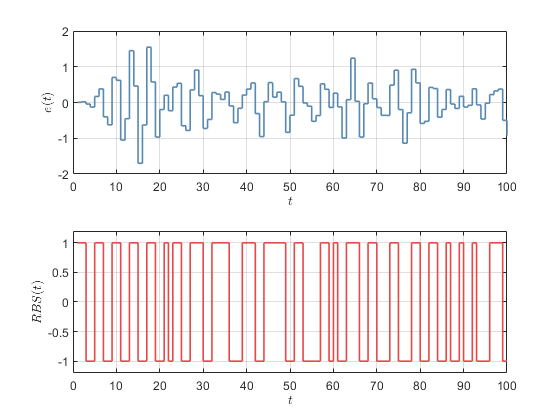

myEx131A

**Figura 1:** *Ruído gaussiano filtrado pelo passa-faixa e sinal RBS originado do ruído gaussiano.*

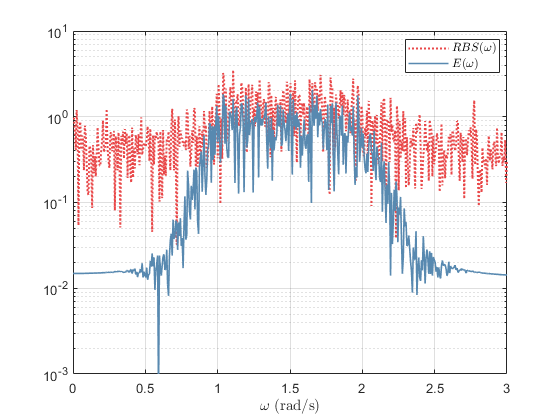

myEx131B

**Figura 2:** *Espectro do sinal gaussiano e do sinal binário aleatório. *

Também é possível escolher $u(t)$ como um sinal binário pseudo-aleatório, isto é, um sinal periódico, determinístico, com propriedades semelhantes ao ruído branco gerado pela seguinte equação diferencial:


$$u(t)=\text{rem}(A(q)u(t),2) = \text{rem}(a_1u(t-1)+...+a_nu(t-n),2)$$


para $\text{rem}(x,2)$ o resto da divisão de $x$ por $2$. Como esse sinal deve ser periódico, o período máximo de um sinal PRBS é $2^n-1$, uma vez que o vetor $[u(t-1)\;...\;u(t-n)]$ pode assumir até $2^n$ valores.

Outra escolha possível para o sinal de entrada é a soma de senoides:


$$u(t)=\sum_{k=1}^da_k\cos(\omega_kt+\Phi_k)$$


cujo espectro é:


$$\Phi_u(\omega=2\pi\sum_{k=1}^d\frac{a_k^2}{4}[\delta(\omega-\omega_k)+\delta(\omega+\omega_k)]$$


O problema com esse tipo de sinal é que a potência de $u(t)$ é $\sum a_k^2/2$. Se todas as senoides estiverem em fase, a amplitude quadrática é $(\sum a_k)^2$. Se todos os $a_k$ forem iguais, o fator $C_r$ pode alcançar $\sqrt{2d}$. Então, o objetivo é manter as senoides da soma o mais distante em fase possível para garantir um menor fator $C_r$.

Uma solução é a nomeada escolha de fase de Schroeder, para o qual $\Phi_1$ é arbitrário e $\Phi_k = \Phi_1-\frac{k(k-1)}{d}\pi$ para $2\leq k\leq d$. Outra solução é aplicar uma senoide (*Chirped Sinusoid*) cuja frequência muda continuamente sobre uma banda $\Omega:\omega_1\leq\omega\leq\omega_2$ no período $0\leq t \leq M$:


$$u(t)=A\cos{\big(\omega_1t+(\omega_2-\omega_1)t^2/(2M)\big)}$$


O fator $C_r$ para esse sinal é $\sqrt2$, assim como uma senoide pura. Porém, permite o controle de uma banda de frequência maior. 

#### Exemplo 13.2: Sinais senoidais

Considere o sinal de soma de senoides para $10$ frequências linearmente distribuídas entre o intervalo $1\leq\omega\leq2$ rad/s. Inicialmente, será considerado o sinal $u(t)=\sum_{k=1}^da_k\cos(\omega_kt)$. Em seguida, será computado o valor de $u_R(t)=\sum_{k=1}^da_k\cos(\omega_kt+\Phi_k)$, para $\Phi_k$ um valor aleatório. Por fim, serão computadas a aproximação para a escolha de fase de Schroeder ($u_S(t)$) e para uma senoide com frequência mutável ($u_C(t)$). Esses sinais estão ilustrados na Figura 3. Analogamente, o espectro para cada sinal está ilustrado na Figura 4. Fica evidente a suavização da magnitude da senoide "*chirped*" em comparação aos demais sinais de entrada tanto no tempo, quanto no domínio da frequência.

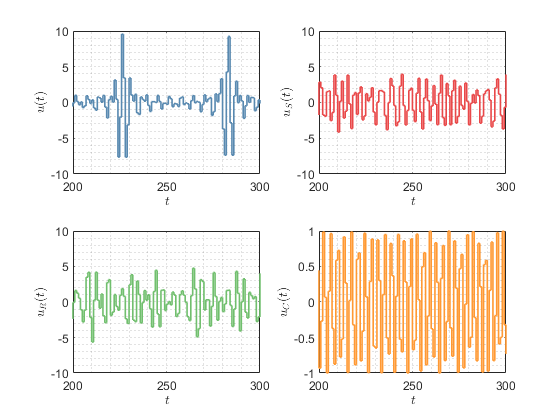

myEx132A

**Figura 3:** Sinais $u(t)$ (soma de senoides com fases equivalentes e nulas), $u_S(t)$ (escolha de fase de Schroeder), $u_R(t)$ (soma de senoides com fases aleatórias) e $u_c(t)$ ("*Chirped" senoide)*.

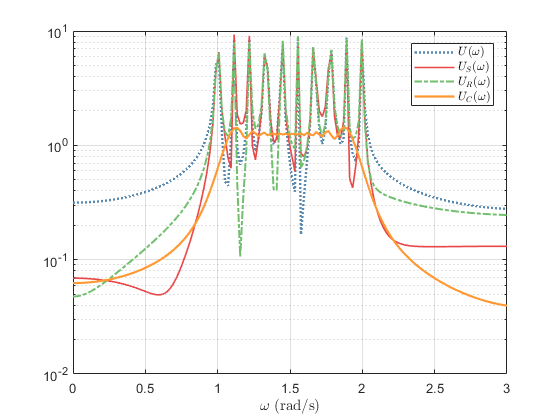

myEx132B

**Figura 4:** Espectro dos sinais $u(t)$, $u_S(t)$, $u_R(t)$ e $u_c(t)$.

## Pré-processando dados

É importante que os dados coletados do experimento sejam pré-processados antes de serem aplicados em algoritmos de estimação, uma vez que podem apresentar:

- Distúrbios com altas frequências (acima da banda de interesse na modelagem);

- *Outliers* ou dados não contínuos;

- *Drifts* ou níveis de *offset* em baixas frequências, possivelmente de caráter periódico.

Dessa forma, é interessante remover os distúrbios dos dados antes de aplicar em um algoritmo de estimação. Outra opção é considerar, no modelo estimado, um ruído que considere essas perturbações nos dados.

Valores mal detectados (*outliers*) são facilmente verificados pelo diagrama de resíduo $r(t)=y(t)-\hat y(t|\hat \theta)$. 

### Exemplo 14.1: Remoção de *outliers*

Como exemplo, considere o sistema simulado:


$$y(t)-2.85y(t-1)+2.717y(t-2)-0.865y(t-3)=u(t-1)+u(t-2)+u(t-3)+e(t)+0.7e(t-1)+0.2e(t-3)$$


Os valores de $y(313)$ a $y(320)$ de $600$ amostras foram artificialmente anuladas. O sinal de saída e o resíduo para a estimativa do método de mínimos quadrados não recursivo estão ilustrados na Figura 5. Observando o redísuo, é evidente que as estimativas do modelo são interferidas em $t=318$. Os parâmetros finais desse modelo para $600$ amostras foi denominado $\hat\theta_1$. 

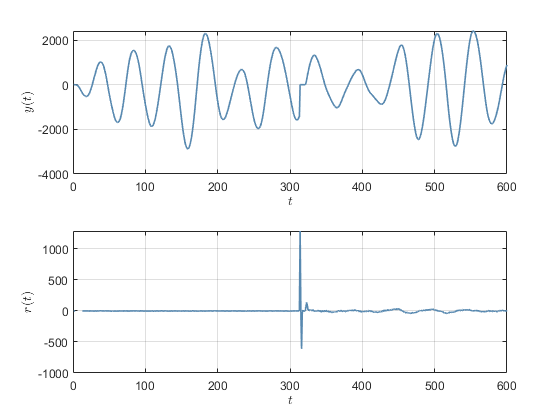

warning('off','all'); myLS

**Figura 5: ***Saída do sistema com outliers e resíduos para o modelo *$\hat\theta_1$.

Outro modelo $\hat\theta_2$ foi estimado para $N=300$ amostras, isto é, antes do "*glitch*" na captura dos dados. A seguir, estão ilustrados os vetores estimados para os dois modelos:

myLS2

theta_LS1 =    -1.4694    0.0400    0.4527    2.0727   -2.9574    4.9850


theta_LS2 =    -2.8577    2.7322   -0.8725    1.1157    1.1788    1.1308


É evidente que, devido aos *outliers, *o vetor de parâmetros estimados resultantes de $\hat\theta_1$ está muito longe do valor real $\theta_0$ em relação ao modelo $\hat\theta_2$. Para evitar esse desvio no ajuste, é possível cortar o segmento dos dados cujos valores são duvidosos. No caso de sistemas com múltiplas entradas e saídas, é melhor tratar os dados faltosos como parâmetros desconhecidos. Os métodos de estimação para esse último caso podem ser encontrados na sessão 14.2 da literatura de referência [1].

## **Referências bibliográficas**

[1] L. LJUNG. **System Identification: Theory for the User**. Pearson, 1998. 2nd edition, ISBN 9788131744956.